### **LOGISTIC REGRESSION & VISUALIZATION OF DATA (by Dilhara Liyanaaratchi)**

**Summary of the Data Set**

clear all
clc

tic
T = readtable("Invistico_Airline.csv"); % Importing the data as a table

summary(T);

Variables:

    satisfaction: 129880×1 cell array of character vectors

        Properties:
            Description:  satisfaction
    Gender: 129880×1 cell array of character vectors

        Properties:
            Description:  Gender
    CustomerType: 129880×1 cell array of character vectors

        Properties:
            Description:  Customer Type
    Age: 129880×1 double

        Properties:
            Description:  Age
        Values:

            Min           7   
            Median       40   
            Max          85   

    TypeOfTravel: 129880×1 cell array of character vectors

        Properties:
            Description:  Type of Travel
    Class: 129880×1 cell array of character vectors

        Properties:
            Description:  Class
    FlightDistance: 129880×1 double

        Properties:
            Description:  Flight Distance
        Val

**Missing values**


% As per the summary it is identified that there are 393 missing values in
% the attribute Arrival delay in minutes. And as compared it to the number
% of observations since it is a small amount we can remove the missing
% observations.

CD = rmmissing(T,'MinNumMissing',1); % removed the rows with missing data

**Attribute summary via visualization**

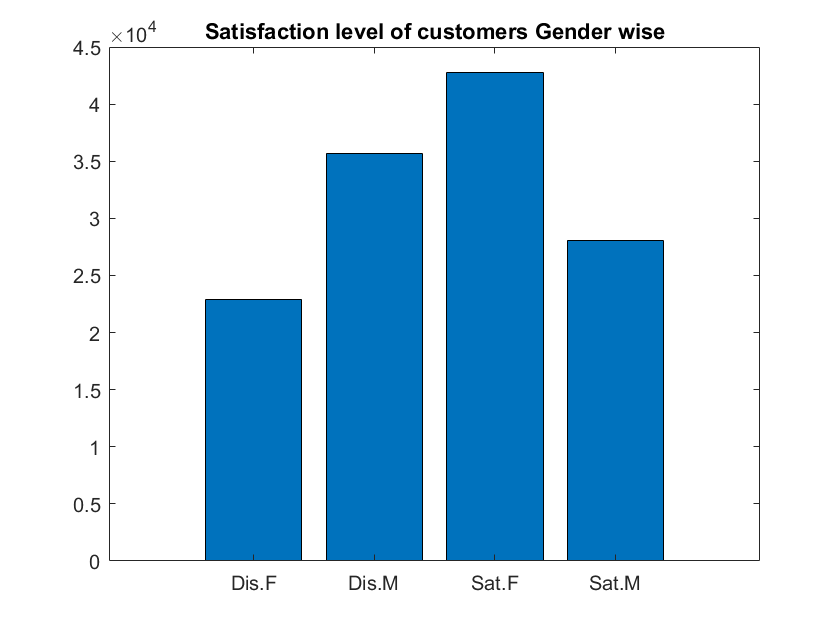

Gen = groupcounts(CD,{'satisfaction','Gender'});
CT = groupcounts(CD,{'satisfaction','CustomerType'});
ToT = groupcounts(CD,{'satisfaction','TypeOfTravel'});
C = groupcounts(CD,{'satisfaction','Class'});

GenL = {'Dis.F','Dis.M','Sat.F','Sat.M'};
bar(Gen.GroupCount);
xticklabels(GenL);
title('Satisfaction level of customers Gender wise');

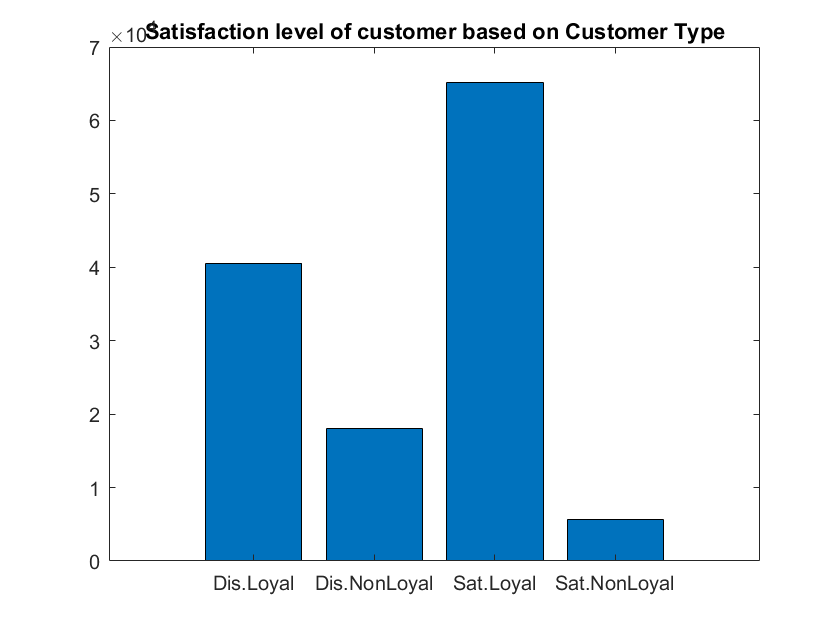


CTL = {'Dis.Loyal','Dis.NonLoyal','Sat.Loyal','Sat.NonLoyal'};
bar(CT.GroupCount);
xticklabels(CTL);
title('Satisfaction level of customer based on Customer Type')

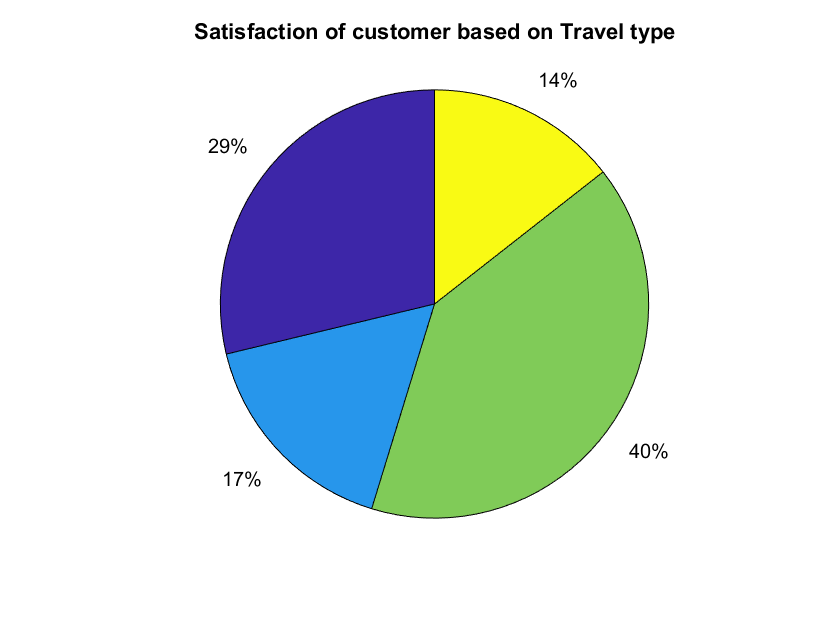


ToTL = {'Dis.Bus','Dis.Per','Sat.Bus','Sat.Per'};
pie(ToT.Percent);
xticklabels(ToTL);
title('Satisfaction of customer based on Travel type');

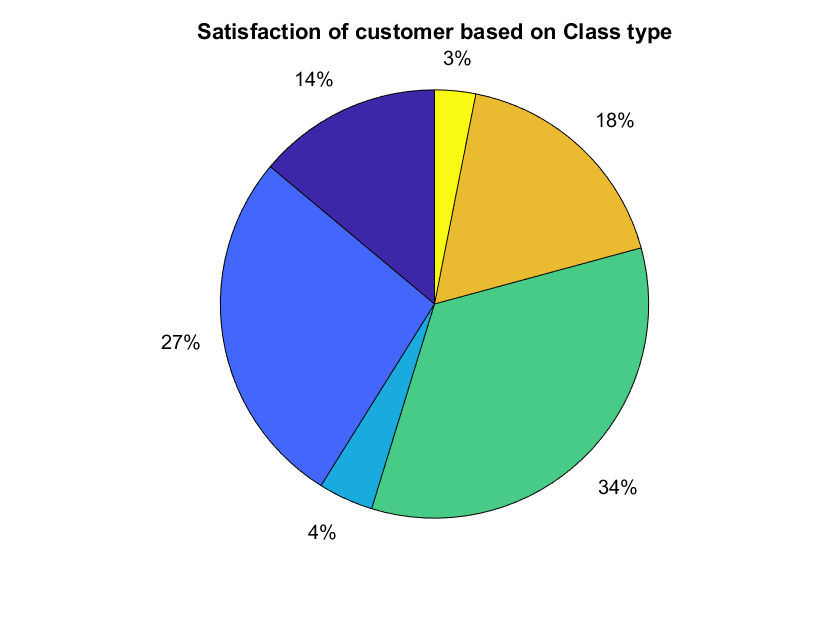


pie(C.Percent);
title('Satisfaction of customer based on Class type');

**Convert Categories to nominal variables**

% Converting Gender

[grpG,genderVals] = findgroups(CD.Gender);
CD.Gender = grpG;

% Converting Satisfaction
[grpS,satisVals] = findgroups(CD.satisfaction);
CD.satisfaction = grpS;

% Converting Customer Type
[grpCT,CTVals] = findgroups(CD.CustomerType);
CD.CustomerType = grpCT;

% Converting Type of Travel
[grpToT,ToTVals] = findgroups(CD.TypeOfTravel);
CD.TypeOfTravel = grpToT;

% Converting Class
[grpC,ClassVals] = findgroups(CD.Class);
CD.Class = grpC;

**Logistic Regression Analysis**

% Splitting the data

Y = CD.satisfaction;
X = [CD.Gender, CD.CustomerType, CD.Age, CD.TypeOfTravel, CD.Class, CD.FlightDistance, CD.SeatComfort, CD.Departure_ArrivalTimeConvenient, CD.FoodAndDrink, CD.GateLocation, CD.InflightWifiService, CD.InflightEntertainment, CD.OnlineSupport, CD.EaseOfOnlineBooking, CD.On_boardService, CD.LegRoomService, CD.BaggageHandling, CD.CheckinService, CD.Cleanliness, CD.OnlineBoarding, CD.DepartureDelayInMinutes, CD.ArrivalDelayInMinutes];


Y = double(Y)-1;

rng(1)
cv = cvpartition(length(X),'holdout',0.3);

% Training set
Xtrain = X(training(cv),:);
Ytrain = Y(training(cv),:);

% Testing set
Xtest = X(test(cv),:);
Ytest = Y(test(cv),:);

mdl_lr = fitglm(Xtrain,Ytrain,'Distribution','binomial','Link','logit');

ptest = predict(mdl_lr,Xtest);

Y_ptest = round(ptest) + 1

Y_ptest =      1
     1
     2
     1
     1
     1
     1
     1
     1
     1


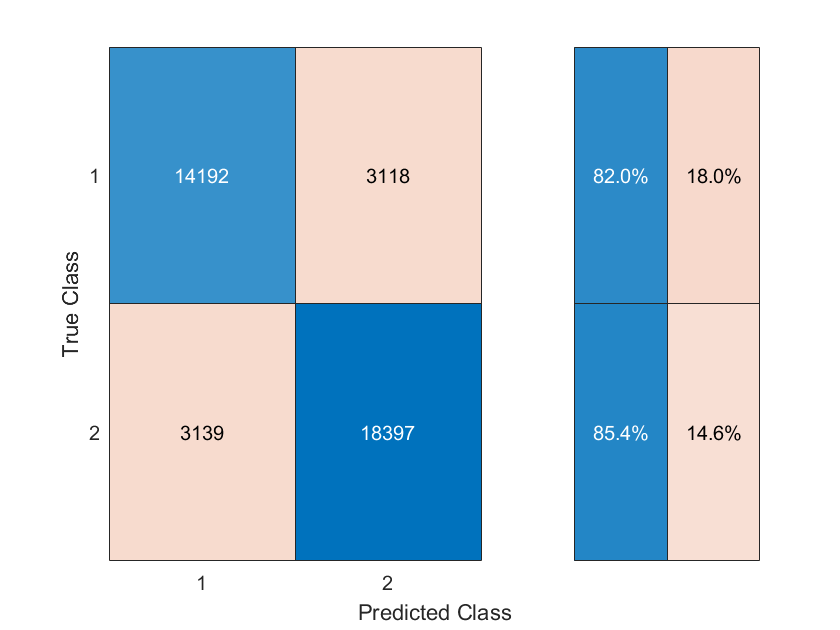


cmglm = confusionchart(double(Ytest)+1,Y_ptest,'RowSummary','row-normalized');


[xxtest,yytest,Tresholds,auctest] = perfcurve(Ytest,ptest,1);

toc

Elapsed time is 5.908907 seconds.


**Calculating the Influence on each attributes**

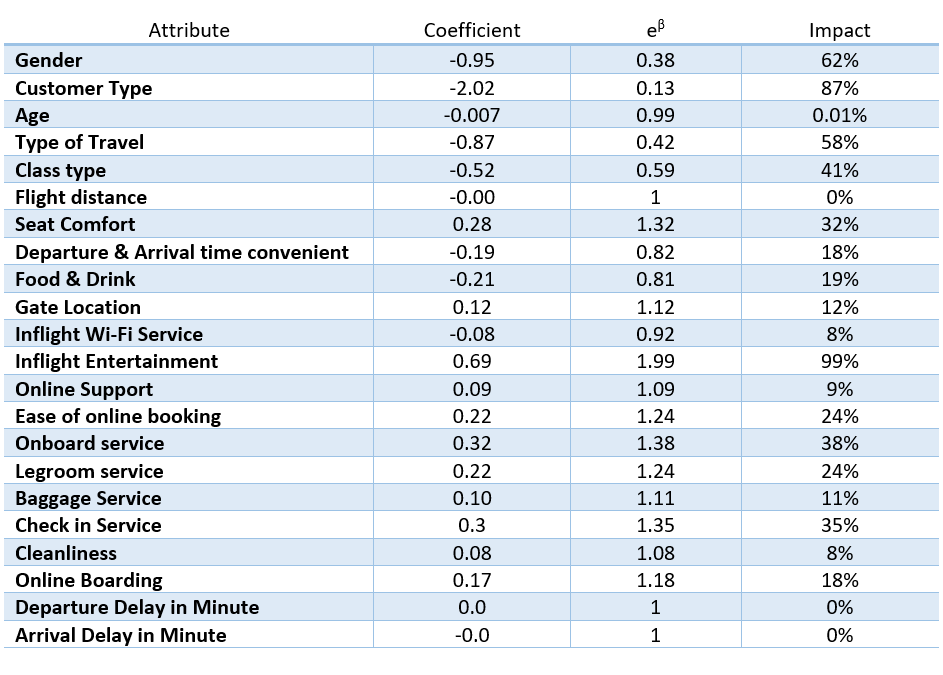

### **DECISION TREE (by Shageerthana Sathiyamoorthy)**

%Importing the data
T1 = readtable ("Invistico_Airline.csv");

rng(1);
summary(T1)

Variables:

    satisfaction: 129880×1 cell array of character vectors

        Properties:
            Description:  satisfaction
    Gender: 129880×1 cell array of character vectors

        Properties:
            Description:  Gender
    CustomerType: 129880×1 cell array of character vectors

        Properties:
            Description:  Customer Type
    Age: 129880×1 double

        Properties:
            Description:  Age
        Values:

            Min           7   
            Median       40   
            Max          85   

    TypeOfTravel: 129880×1 cell array of character vectors

        Properties:
            Description:  Type of Travel
    Class: 129880×1 cell array of character vectors

        Properties:
            Description:  Class
    FlightDistance: 129880×1 double

        Properties:
            Description:  Flight Distance
        Val

T = rmmissing(T1,'MinNumMissing',1); %remove the missing values

a = (T.satisfaction); %Response variable 
T.satisfaction = [];
Y = grp2idx(a); % convert categorical to numbers
m = grp2idx(T.Gender);
n = grp2idx(T.CustomerType);
o = grp2idx(T.TypeOfTravel);
p = grp2idx(T.Class);
X = [m,n,T.Age,o,p,T.FlightDistance,T.SeatComfort,T.Departure_ArrivalTimeConvenient,T.FoodAndDrink,T.GateLocation,T.InflightWifiService,T.InflightEntertainment,T.OnlineSupport,T.EaseOfOnlineBooking,T.On_boardService,T.LegRoomService,T.BaggageHandling,T.CheckinService,T.Cleanliness,T.OnlineBoarding,T.DepartureDelayInMinutes,T.ArrivalDelayInMinutes];%Predictor variable

%Divide the data into training and testing 
cv = cvpartition(length(X),'holdout',0.4);
Xtrain = X(training(cv),:);
Xtest = X(test(cv),:);
Ytrain = Y(training(cv),:);
Ytest = Y(test(cv),:);
%Decision tree modelling
t = fitctree(Xtrain,Ytrain)

t =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [1 2]
           ScoreTransform: 'none'
          NumObservations: 77693


  Properties, Methods


Y_t = predict(t,Xtest);
%confusion matrix
cmtree = confusionchart(Ytest,Y_t)

cmtree =   ConfusionMatrixChart with properties:

    NormalizedValues: [2×2 double]
         ClassLabels: [2×1 double]

  Show all properties


%AUC 
[Xt1,Yt1,Thresholds,AUCt] = perfcurve(Ytest,Y_t,1);

### **SUPPORT VECTOR MACHINE (by Daniela Maldonado Sada)**

clear all
clc
T =readtable('Invistico_Airline.csv',"VariableNamingRule","preserve");
% convert cell variables to categorical
names = T.Properties.VariableNames;
[nrows, ncols] = size(T);
category = false(1,ncols);

for i = 1:ncols
if isa(T.(names{i}),'cell')
category(i) = true;
T.(names{i}) = categorical(T.(names{i}));
end
end

rng('default'); %making sure the results are the same every time
D = dummyvar(T.Class);% encode categorical variables Class
D = array2table(D);
D.Properties;
T = [T ,D];% add new variable to cars
T.Class =[];
% T.satisfaction = double(T.satisfaction);
T.Gender = double(T.Gender);
T.('Customer Type') = double(T.('Customer Type'));
T.('Type of Travel') = double(T.('Type of Travel'));
% remove missing data, there are few missing data in arrival delay
completedata=rmmissing(T,'MinNumMissing',1);

% define model inputs and target
X = table2array(completedata(:,2:end));
Y = dummyvar(completedata.satisfaction);
Y=Y(:,1);

**Spliting data in traing and test**

rng 'default'
[L W]=size(X);
XSVM = cvpartition(L,'holdout',0.40);
% c = cvpartition(n,'KFold',k)

%Training set
Xtrain = X(training(XSVM),:);
Ytrain = Y(training(XSVM),:);

%Test set
Xtest = X(test(XSVM),:);
Ytest = Y(test(XSVM),:);

disp('Training Set');

Training Set


tabulate(Ytrain)

  Value    Count   Percent
      0    42468     54.66%
      1    35225     45.34%


disp('Test Set');

Test Set


tabulate(Ytest);

  Value    Count   Percent
      0    28414     54.86%
      1    23380     45.14%


**Modeling SVM**

cvp = cvpartition(Ytrain, 'KFold', 5);
mdlSVM = fitcsvm(Xtrain,Ytrain,'Standardize',1,'KernelFunction','RBF',...
    'KernelScale','auto');
CVSVMModel = crossval(mdlSVM);
loss_vector_svm=kfoldLoss(CVSVMModel)

loss_vector_svm = 0.0512

accuracy_vector_svm=1-loss_vector_svm

accuracy_vector_svm = 0.9488

**Predicting **

%confusion chart
[predicted_classes_svm, Posterior_svm] = kfoldPredict(CVSVMModel);

**Makig the AUC curve to see the performance**

[Xsvm,Ysvm,~,AUC_Svm] = perfcurve(Ytrain,Posterior_svm(:,2),'1');
figure;
plot(Xsvm,Ysvm)
xlabel('False positive rate'); ylabel('True positive rate');
CorX=corr(X)

CorX =     1.0000   -0.0308    0.0090    0.0092    0.1208   -0.0721    0.0520   -0.0591   -0.0110   -0.0316   -0.1409   -0.0903   -0.0822   -0.0570   -0.0714   -0.0170   -0.0185   -0.0153   -0.0475    0.0031    0.0013    0.0085   -0.0025   -0.0115
   -0.0308    1.0000   -0.2843   -0.3082    0.0190   -0.0430   -0.1861   -0.0489   -0.0003   -0.0736   -0.2361   -0.1863   -0.1499   -0.0853   -0.0972   -0.0005   -0.0444   -0.0020   -0.1066    0.0041    0.0047   -0.0856    0.1184   -0.0621
    0.0090   -0.2843    1.0000   -0.0449   -0.2494    0.0085    0.0389    0.0155   -0.0008    0.0140    0.1303    0.1213    0.0717    0.0665    0.0837   -0.0156    0.0316   -0.0186    0.0379   -0.0093   -0.0112    0.1389   -0.1328   -0.0128
    0.0092   -0.3082   -0.0449    1.0000   -0.1232    0.0173    0.1915   -0.0314   -0.0138   -0.0189   -0.0791   -0.0390   -0.0254    0.0359    0.0141    0.0486    0.0575    0.0585   -0.0089   -0.0063   -0.0058   -0.5521    0.5010    0.1025
    0.1208    0.0190   -0.249

**Making the confusion chart to see the true and false positive**

Y_svm = predict (mdlSVM, Xtest)

Y_svm =      0
     0
     0
     0
     0
     0
     0
     0
     0
     1


cmsvm = confusionchart(Ytest,Y_svm,'RowSummary','row-normalized')

### **ARTIFICIAL NEURAL NETWORK (by Ali Izadkhah)**

clear all
clc

% read data table
T =readtable('Invistico_Airline.csv',"VariableNamingRule","preserve");

% get insight from the data
summary(T)

% convert cell variables to categorical
names = T.Properties.VariableNames;
[nrows, ncols] = size(T);

category = false(1,ncols);
for i = 1:ncols
if isa(T.(names{i}),'cell')
category(i) = true;
T.(names{i}) = categorical(T.(names{i}));
end
end

rng('default');

% encode categorical variables Class
D = dummyvar(T.Class);
D = array2table(D);
D.Properties;
% add new variable to cars
T = [T ,D];
T.Class =[];

%T.satisfaction = double(T.satisfaction);
T.Gender = double(T.Gender);
T.('Customer Type') = double(T.('Customer Type'));
T.('Type of Travel') = double(T.('Type of Travel'));

% remove missing data, there are few missing data in arrival delay
completedata=rmmissing(T,'MinNumMissing',1);

% calculate the training time
tic

% define model inputs and target
inputs = table2array(completedata(:,2:end))';
targets = dummyvar(completedata.satisfaction)';;

% Initialize neural network
hiddenLayerSize = 17;
net = patternnet(hiddenLayerSize);

% divide data to train, vailidation and test sets
net.divideParam.trainRatio = 70/100;
net.divideParam.valRatio = 20/100;
net.divideParam.testRatio = 10/100;

% Train the network
[net,tr] = train(net,inputs,targets);

% Predict response
scoreTest = net(inputs(:,tr.testInd));
[~,yPred] = max(scoreTest);

% Evaluate classification with confusion matrix
cstest = completedata.satisfaction(tr.testInd);
yTrue = double(cstest);
confusionchart(yTrue,yPred','RowSummary','row-normalized');

% Determine validation error
cstest = completedata.satisfaction(tr.testInd);
validErr = 100*nnz(yPred' ~= double(cstest))/length(cstest)

% calculate model accuracy
accuracy_final_model= 100-validErr

% calculate recall and precision
tp = sum((yPred' == 1) & (yTrue == 1));
fp = sum((yPred' == 1) & (yTrue == 2));
fn = sum((yPred' == 2) & (yTrue == 1));

precision = tp / (tp + fp);
recall = tp / (tp + fn);
F1 = (2 * precision * recall) / (precision + recall);
recall
precision

% calculate ROC and AUC
[xTr, yTr, TTr, aucTr] = perfcurve(double(completedata.satisfaction(tr.testInd)), scoreTest(1,:)', 1);
aucTr

% Plot ROC curve
figure
plot(xTr, yTr, 'LineWidth',4);
xlabel('False positive rate'); ylabel('True positive rate');
title('ROC Curve with ANN model')

toc